DATA_FILEPATH = "ECE113/ece113dw_project/audio_data";

USE_MELSPECTRUM = false;
USE_MFCC = true;
USE_MFCC_DELTA = false;

% Create datastore
dataset = fullfile(DATA_FILEPATH);

ads = audioDatastore(dataset, ...
    IncludeSubfolders=true, ...
    FileExtensions=".wav", ...
    LabelSource="foldernames");

% Split into train / test

[train,test] = splitEachLabel(ads,0.6,'randomize');

% Extract Features
afe = audioFeatureExtractor( ...
    SampleRate=8000, ...
    FFTLength=512, ...
    Window=hamming(512,"periodic"), ...
    OverlapLength=128, ...
    melSpectrum=USE_MELSPECTRUM, mfcc=USE_MFCC, ...
    mfccDelta=USE_MFCC_DELTA);

num_bands = 32;
if(USE_MELSPECTRUM)
    setExtractorParameters(afe,"melSpectrum",NumBands=num_bands,WindowNormalization=false);
end
if(USE_MFCC)
    setExtractorParameters(afe,"mfcc",NumCoeffs=13);
end

train_d = extract(afe,train);
test_d = extract(afe,test);

% Read in data
%train_d = readall(train_tf);
%test_d = readall(test_tf);

train_d = cat(4,train_d{:});
test_d = cat(4,test_d{:});
[numHops,numBands,numChannels,numFiles] = size(train_d)

numHops = 41

numBands = 13

numChannels = 1

numFiles = 103


% Separate Labels
train_labels = train.Labels;
test_labels = test.Labels;

% Define model
classes = categories(train_labels);
num_classes = numel(classes);
num_filters = 8;

layers = [
    imageInputLayer([numHops,afe.FeatureVectorLength])
    
    convolution2dLayer(3,num_filters,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,2*num_filters,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,4*num_filters,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(num_classes)
    softmaxLayer
    classificationLayer(Classes=classes)];

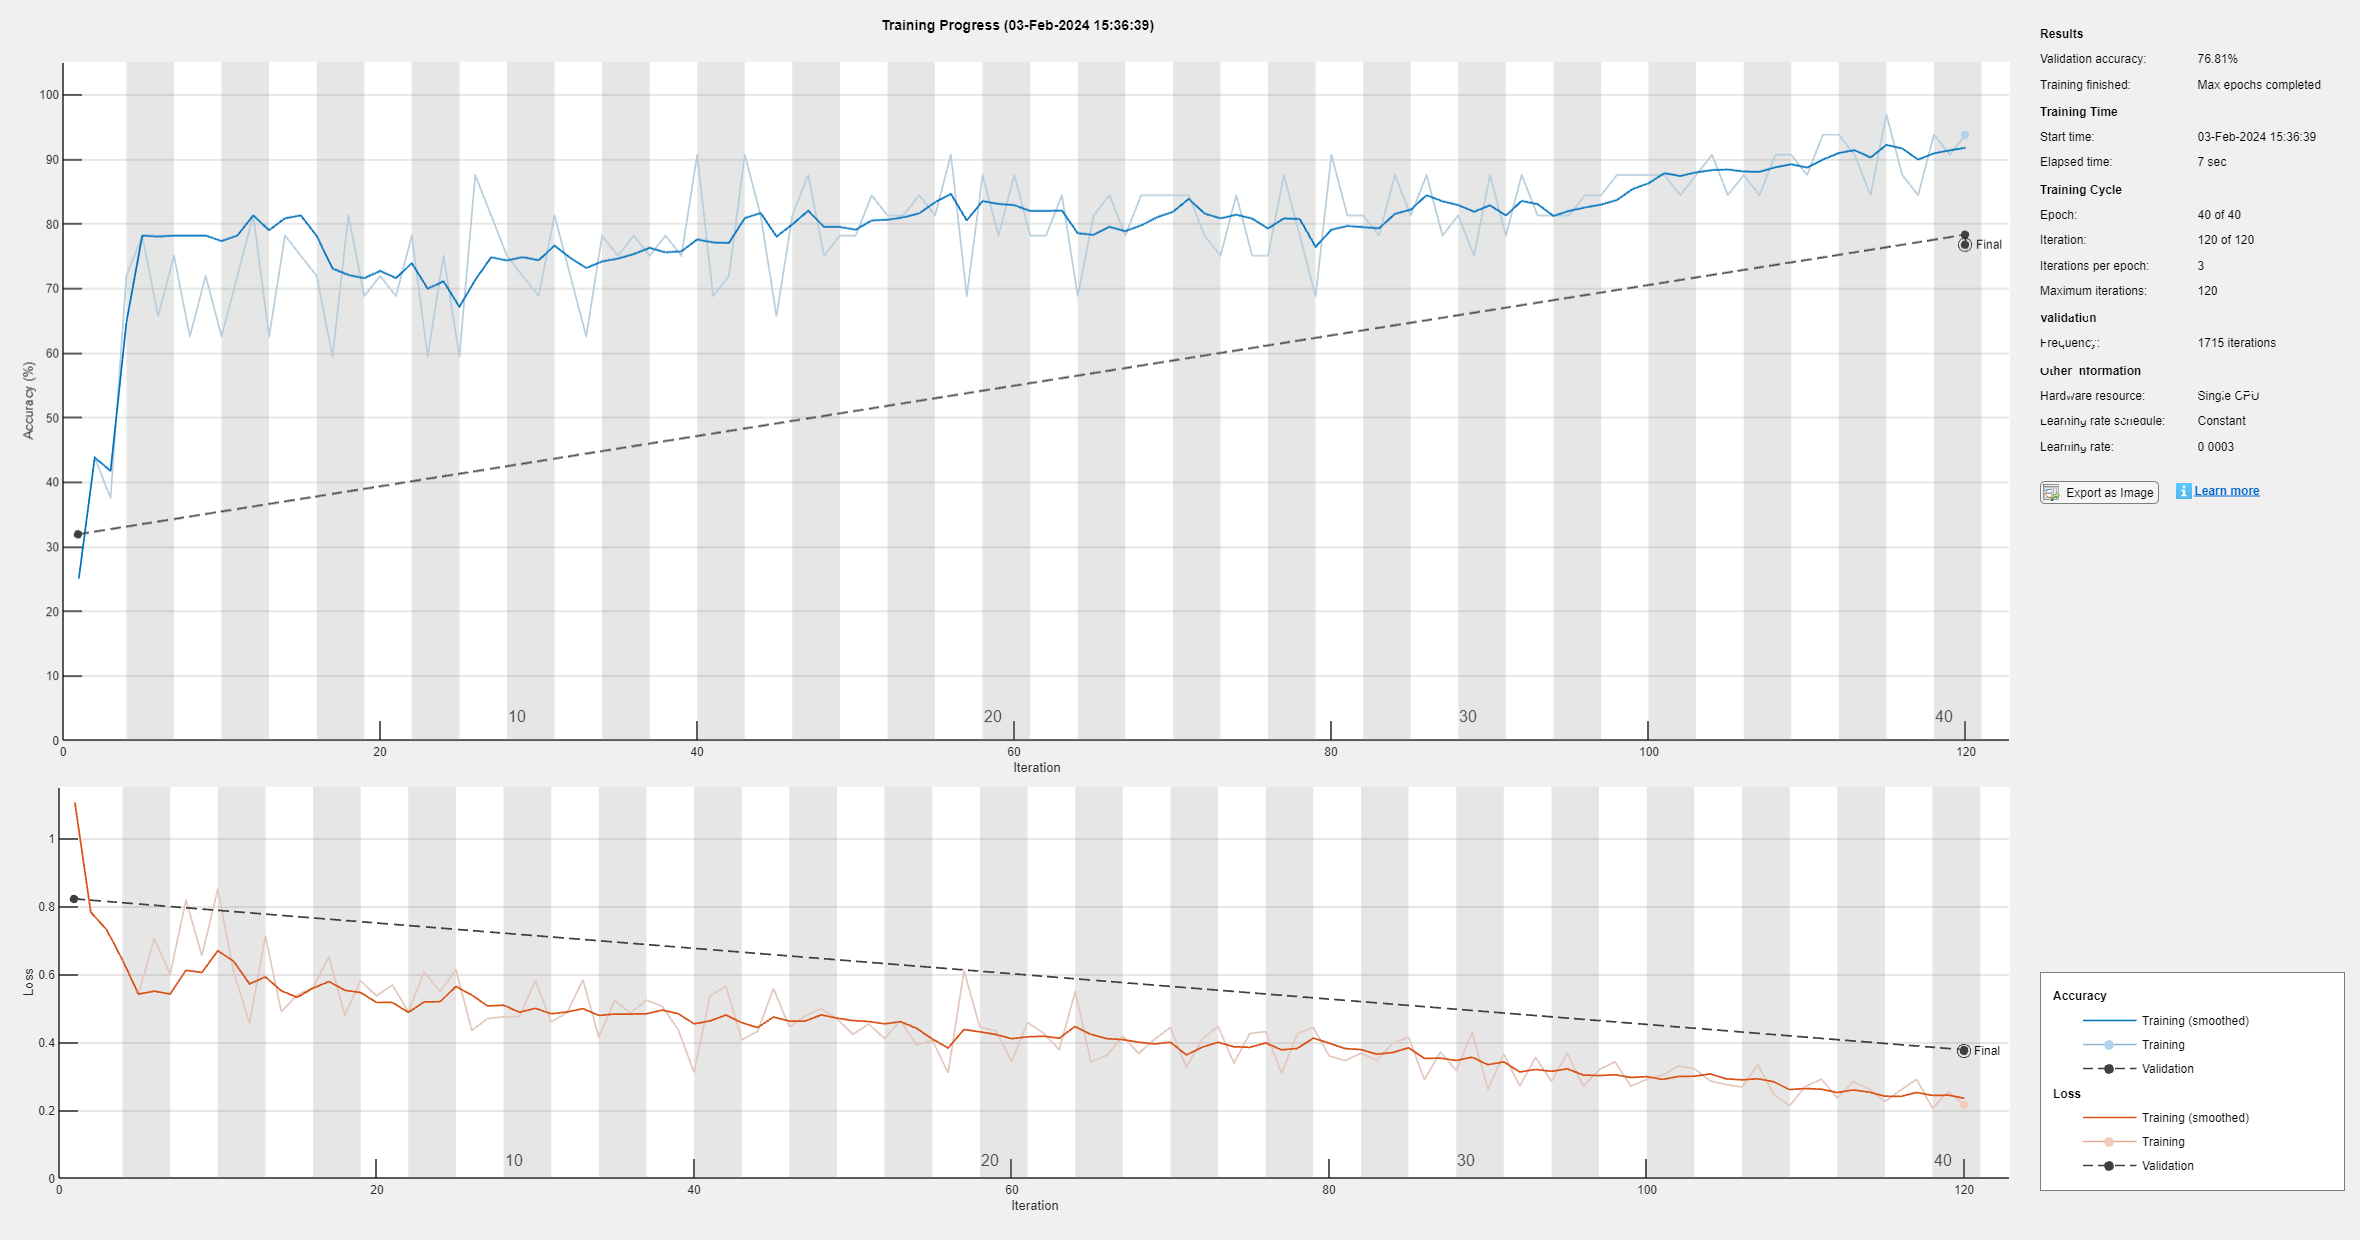

% Train model
miniBatchSize = 32;
validationFrequency = floor(numel(train_d)/miniBatchSize);
options = trainingOptions("adam", ...
    InitialLearnRate=3e-4, ...
    MaxEpochs=40, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationData={test_d,test_labels}, ...
    ValidationFrequency=validationFrequency);

trainedNet = trainNetwork(train_d,train_labels,layers,options);

test_pred = classify(trainedNet,test_d);
validationError = mean(test_pred ~= test_labels);
train_pred = classify(trainedNet,train_d);
trainError = mean(train_pred ~= train_labels);

disp(["Training error: " + trainError*100 + " %";"Validation error: " + validationError*100 + " %"])

    "Training error: 7.767 %"
    "Validation error: 23.1884 %"



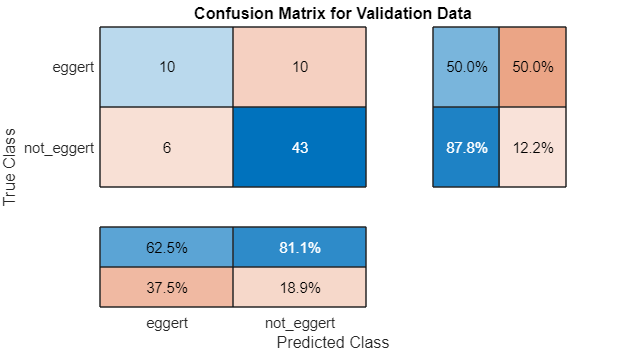

figure(Units="normalized",Position=[0.2,0.2,0.5,0.5]);
cm = confusionchart(test_labels,test_pred, ...
    Title="Confusion Matrix for Validation Data", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");